# **第二章**

2.23 利用Matlab工具箱函数stem，画出单位脉冲响应，单位阶跃序列和斜坡序列的波形。

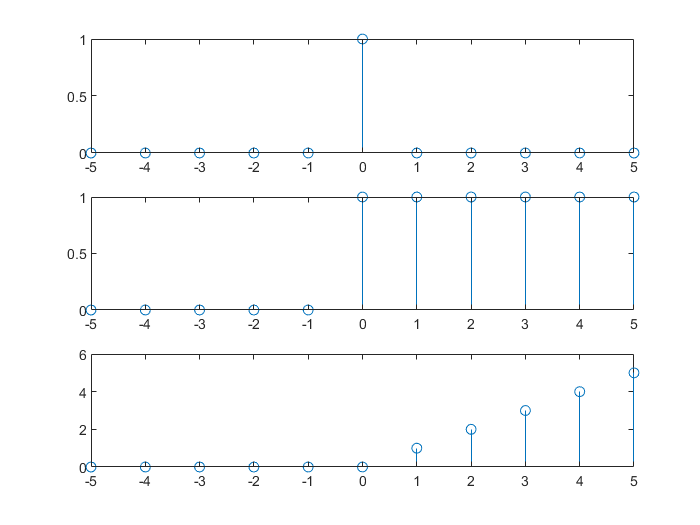

xr=[-5:5];
y1=zeros(11,1);y1(6)=1;
y2=zeros(11,1);y2(6:end ,1)=1;
y3=zeros(11,1);
for i =1:5
    y3(i+6)=y2(i+6)*i;
end
figure(1)
title('2.23');
subplot(3,1,1);
stem(xr,y1);
subplot(3,1,2);
stem(xr,y2);
subplot(3,1,3);
stem(xr,y3);

2.25 已知线性时不变系统的差分方程为$\mathrm{y}\left(\mathrm{n}\right)=-1/2\mathrm{y}\left(\mathrm{n}-1\right)+\mathrm{x}\left(\mathrm{n}\right)+2\mathrm{x}\left(\mathrm{n}-2\right),\mathrm{\ }$若系统的输入序列为$\mathrm{x}\left(\mathrm{n}\right)=\left\lbrace 1,2,3,4,2,1\right\rbrace ,\mathrm{\ }$编写利用递推法计算系统零状态响应的Matlab程序，并算出结果。

x0=1;
x1=[2 3 4 2 1 0 0 0 0];
y1=zeros(100,1);
for i =1:8
    if i==1
        y1(i)=x1(1);
    elseif i==2
        y1(i)=-0.5.*y1(i-1)+x1(i)+2*x0;
    else
        y1(i)=-0.5*y1(i-1)+x1(i)+2*x1(i-2);
    end
end
y1

y1 =     2.0000
    4.0000
    6.0000
    5.0000
    6.5000
    0.7500
    1.6250
   -0.8125
         0
         0


2.27 已知线性时不变系统的差分方程为$\mathrm{y}{\left(\mathrm{n}\right)}=-{\mathrm{a}}_1 y{\left(n-1\right)}-a_2 y{\left(n-2\right)}+bx{\left(n\right)}$其中，${\mathrm{a}}_1 =-0.8,\ a_2 =0.64,\ b=0.866\$

（1）用matlab求解系统的单位脉冲响应，$\mathrm{h}{\left(\mathrm{n}\right)}$，0≤n≤49，并画出$\mathrm{h}{\left(\mathrm{n}\right)}$的波形。

（2）用matlab求解系统的单位阶跃响应$\mathrm{y}{\left(\mathrm{n}\right)}$，0≤n≤100，并画出$\mathrm{y}{\left(\mathrm{n}\right)}$的波形。

（3） 现利用（1）的的前一段构成一个新的系统，其单位脉冲响应为


$$h_1 \left(n\right){\left\{\begin{array}{c}
h{\left(n\right)},\ 0\le n\le 14\\
0,\ \ 其它
\end{array}\right)}$$


  编写求解这个新系统的单位阶跃响应的matlab程序，并计算结果。

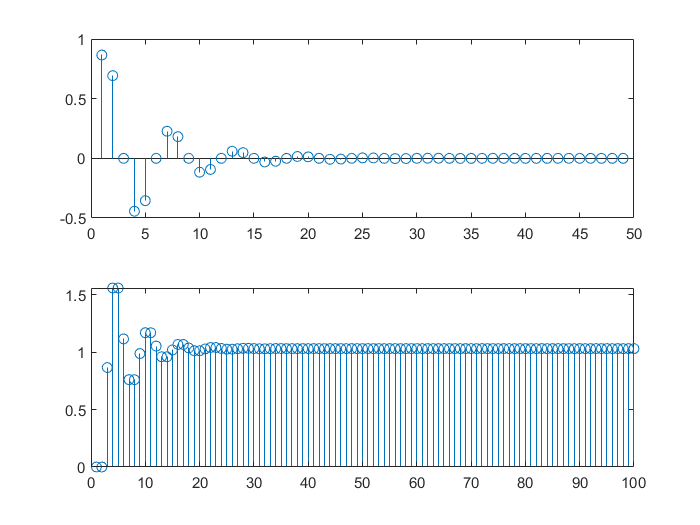

hn=impz([0.866],[1 -0.8 0.64],49);
gn= dstep([0.866],[1 -0.8 0.64],100);
h1n=hn(1:15);
figure(2)
subplot(3,1,1)
stem(hn)
subplot(3,1,2)
stem(gn)

subplot(3,1,3)
stem(h1n)

2.29 已知序列和分别为


$$x{\left(n\right)}={\left\{\begin{array}{c}
-0.5,\ 0,\ 0.5,1,\ n=-1,0,1,2\\
0,其它
\end{array}\right)}$$



$$\mathrm{h}{\left(\mathrm{n}\right)}={\left\{\begin{array}{c}
1,1,1,\ n=-2,-1,0\\
0,\ 其它
\end{array}\right)}$$


试用matlab工具箱conv，计算线性卷积$\mathrm{y}{\left(\mathrm{n}\right)}=\mathrm{x}{\left(\mathrm{n}\right)}\mathrm{*}\mathrm{h}\left(\mathrm{n}\right)$, 并画出$\mathrm{y}\left(\mathrm{n}\right)$的波形。

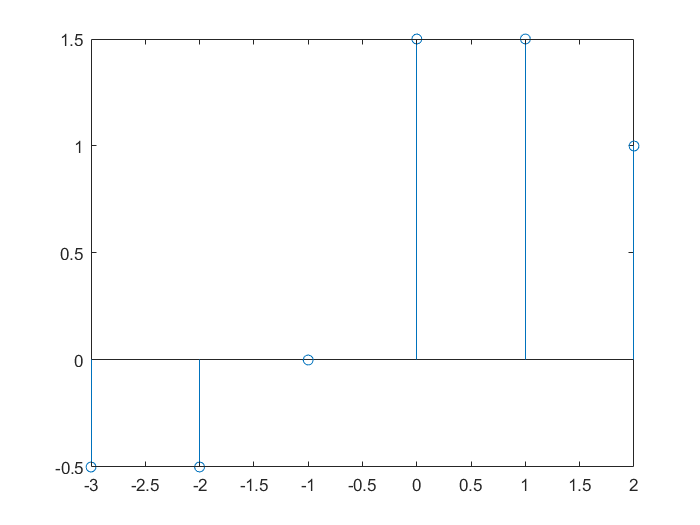

x1=[-0.5 0 0.5 1];
h1=[1  1   1 ];
c1=conv(x1,h1);
figure(3)
stem([-3:2],c1)